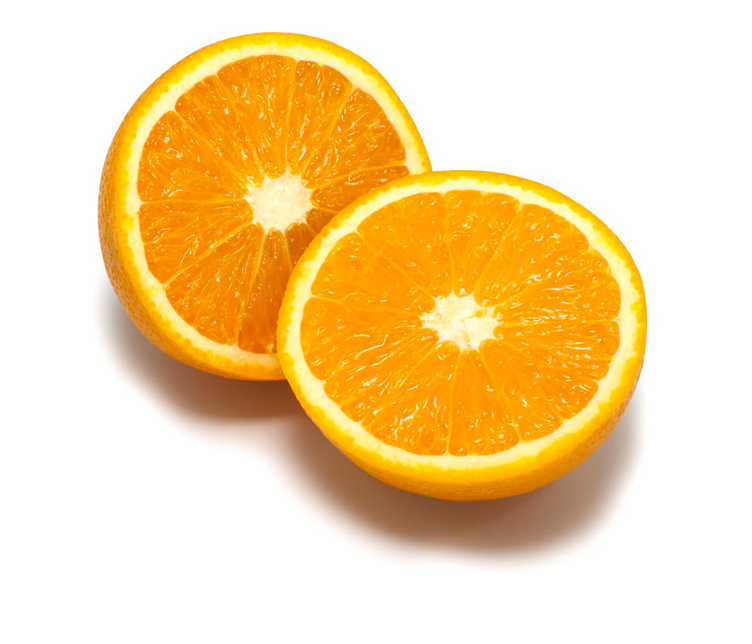

K = 8;               % number of clusters used
L = 6;              % number of iterations
seed = 20;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

I = imread('orange.jpg');
imshow(I);

I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

% [ segm, centers ] = kmeans_segm(I, K, L, seed);
% disp(centers);
% Inew = mean_segments(Iback, segm);
% I = overlay_bounds(Iback, segm);
% imshow(Inew);
% imshow(I);

% Q2
prev_centers = [];
for K = 2:10
    converged = false;
    for L = 1:50
        [ segm, centers ] = kmeans_segm(I, K, L, 'default');
        
        if L > 1
            largest_diff = max(abs(centers - prev_centers),[],'all');
            if largest_diff < 0.5
                converged = true;
                break
            end
        end
        prev_centers = centers;
    end
    if converged == true
        disp(sprintf("K = %i converged at L = %i", K, L));
    end
end

K = 2 converged at L = 2
K = 3 converged at L = 4
K = 4 converged at L = 4
K = 5 converged at L = 8
K = 6 converged at L = 8


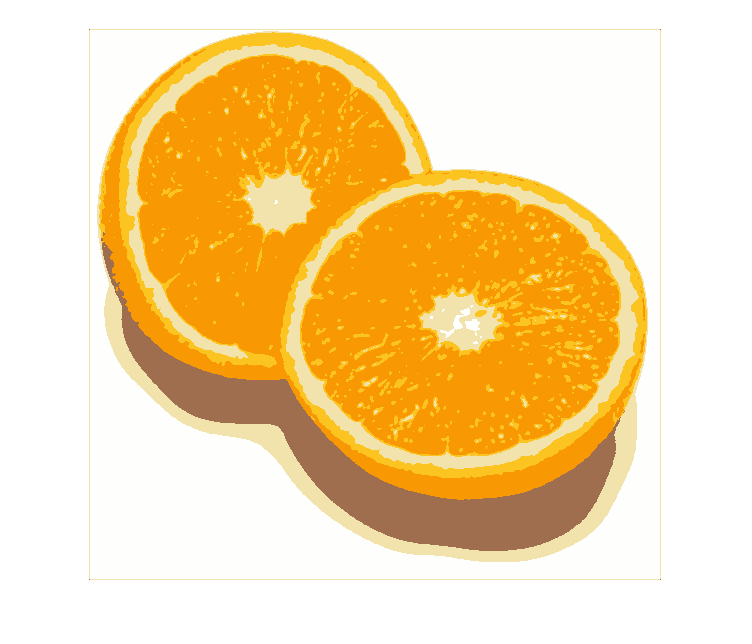

% Q3
K = 10;
L = 20;
[ segm, centers ] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
imshow(Inew);

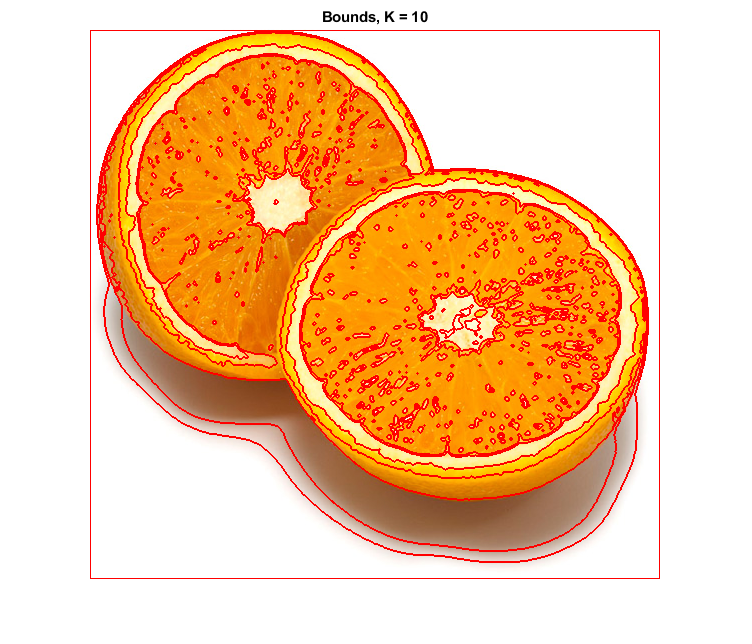

imshow(Ibounds);
title(sprintf("Bounds, K = %i", K));

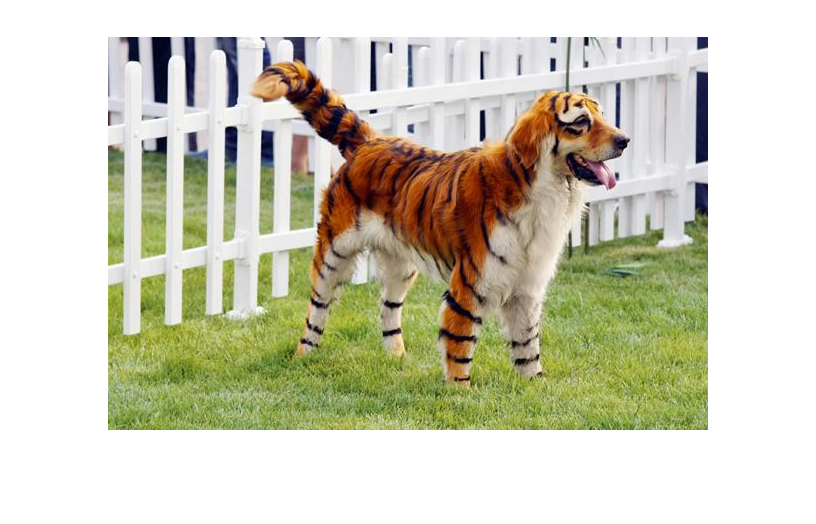

% Q4
K = 8;               % number of clusters used
L = 20;              % number of iterations
seed = 20;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 3.0;   % image preblurring scale

I = imread('tiger3.jpg');
imshow(I);

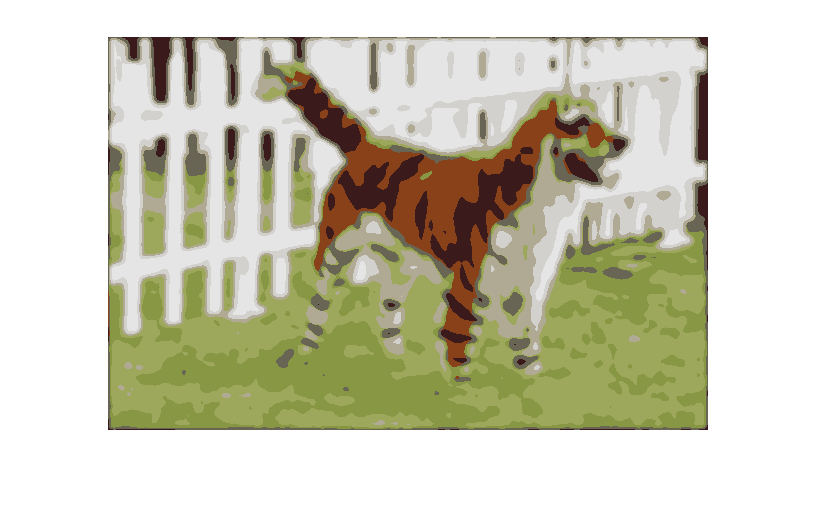

I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

[ segm, centers ] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
imshow(Inew);

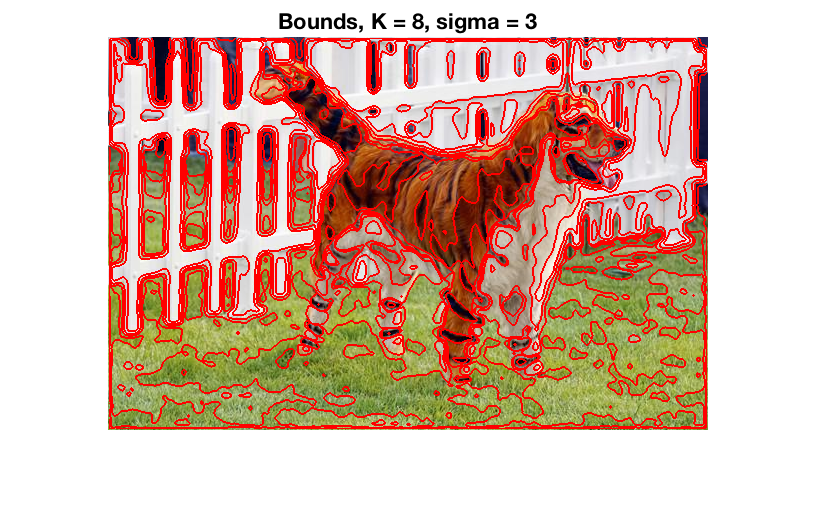

imshow(Ibounds);
title(sprintf("Bounds, K = %i, sigma = 3", K));

% Q5
scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 9.0;  % spatial bandwidth
colour_bandwidth = 4.0;   % colour bandwidth
num_iterations = 40;      % number of mean-shift iterations
image_sigma = 1.0;        % image preblurring scale

I = imread('tiger3.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.230632 seconds.
Elapsed time is 0.615741 seconds.
Search for high density points...


Elapsed time is 0.688693 seconds.
Elapsed time is 0.708286 seconds.
Elapsed time is 0.719204 seconds.
Elapsed time is 0.739637 seconds.
Elapsed time is 0.775299 seconds.
Elapsed time is 0.793025 seconds.
Elapsed time is 0.834873 seconds.
Elapsed time is 0.854027 seconds.
Elapsed time is 0.868650 seconds.
Elapsed time is 0.887833 seconds.
Elapsed time is 0.908965 seconds.
Elapsed time is 0.935253 seconds.
Elapsed time is 0.950782 seconds.
Elapsed time is 0.971436 seconds.
Elapsed time is 1.006528 seconds.
Elapsed time is 1.035226 seconds.
Elapsed time is 1.053029 seconds.
Elapsed time is 1.065026 seconds.
Elapsed time is 1.086447 seconds.
Elapsed time is 1.120474 seconds.
Elapsed time is 1.140688 seconds.
Elapsed time is 1.169767 seconds.
Elapsed time is 1.181432 seconds.
Elapsed time is 1.206404 seconds.
Elapsed time is 1.235323 seconds.
Elapsed time is 1.259297 seconds.
Elapsed time is 1.277702 seconds.
Elapsed time is 1.291764 seconds.
Elapsed time is 1.311014 seconds.
Elapsed time i

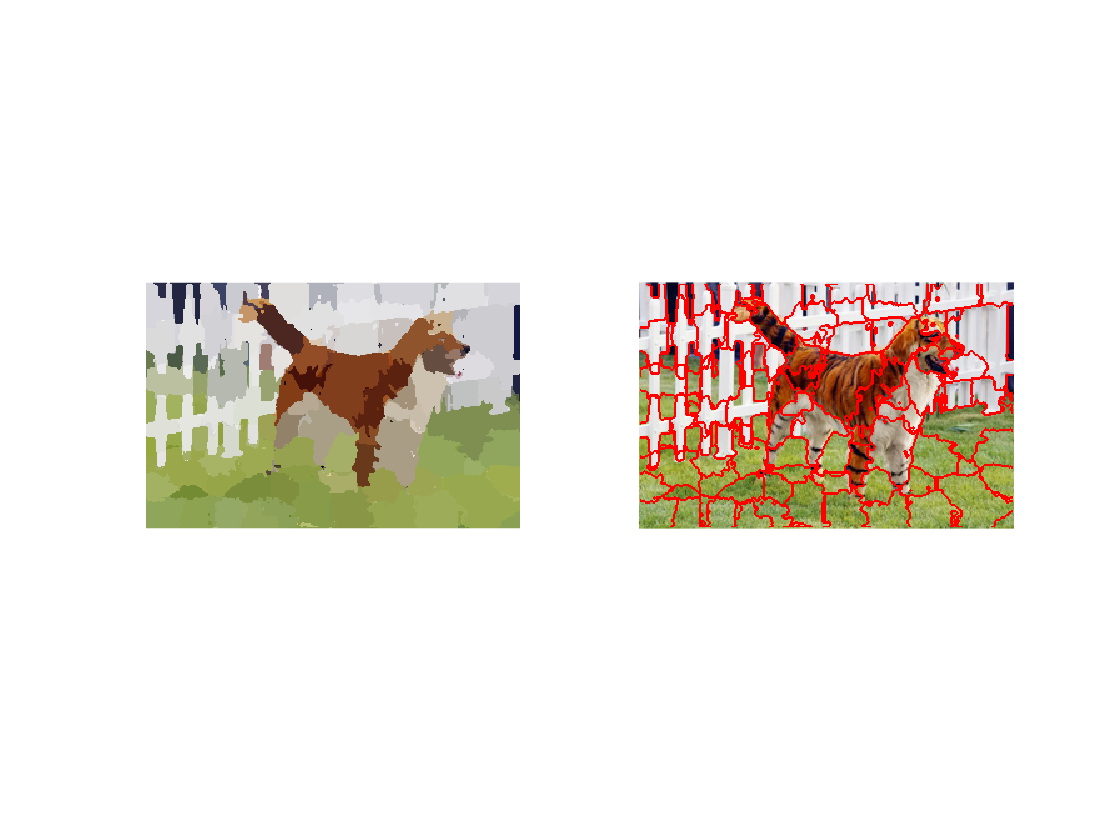

Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(Ibounds);

% Q7
close all;
colour_bandwidth = 22.0; % color bandwidth
radius = 20;              % maximum neighbourhood distance
ncuts_thresh = 0.4;      % cutting threshold
min_area = 100;          % minimum area of segment
max_depth = 4;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Elapsed time is 3.963216 seconds.
Solve eigenvalue problems to find partitions...
Cutting ncut=0.007 sizes=(49079,1530)
Cutting ncut=0.002 sizes=(26975,22104)
Cutting ncut=0.003 sizes=(11980,14995)
Cutting ncut=0.081 sizes=(8478,3502)
Cutting ncut=0.044 sizes=(3820,4658)
Cutting ncut=0.028 sizes=(1647,1855)
Cutting ncut=0.048 sizes=(671,14324)
Cutting ncut=0.146 sizes=(490,181)
Cutting ncut=0.082 sizes=(10081,4243)
Cutting ncut=0.012 sizes=(7224,14880)
Cutting ncut=0.034 sizes=(3772,3452)
Cutting ncut=0.032 sizes=(2702,1070)
Cutting ncut=0.050 sizes=(2995,457)
Cutting ncut=0.020 sizes=(1567,13313)
Cutting ncut=0.087 sizes=(884,683)
Cutting ncut=0.046 sizes=(10219,3094)
Cutting ncut=0.005 sizes=(541,989)
Cutting ncut=0.018 sizes=(215,326)
Cutting ncut=0.051 sizes=(113,102)
Cutting ncut=0.060 sizes=(14,99)
Cutting ncut=0.186 sizes=(51,51)
Cutting ncut=0.031 sizes=(218,108)
Cutting ncut=0.054 sizes=(55,163)
Cutting ncut=0.160 sizes=(54,54)
Cutting ncut=0.011 siz

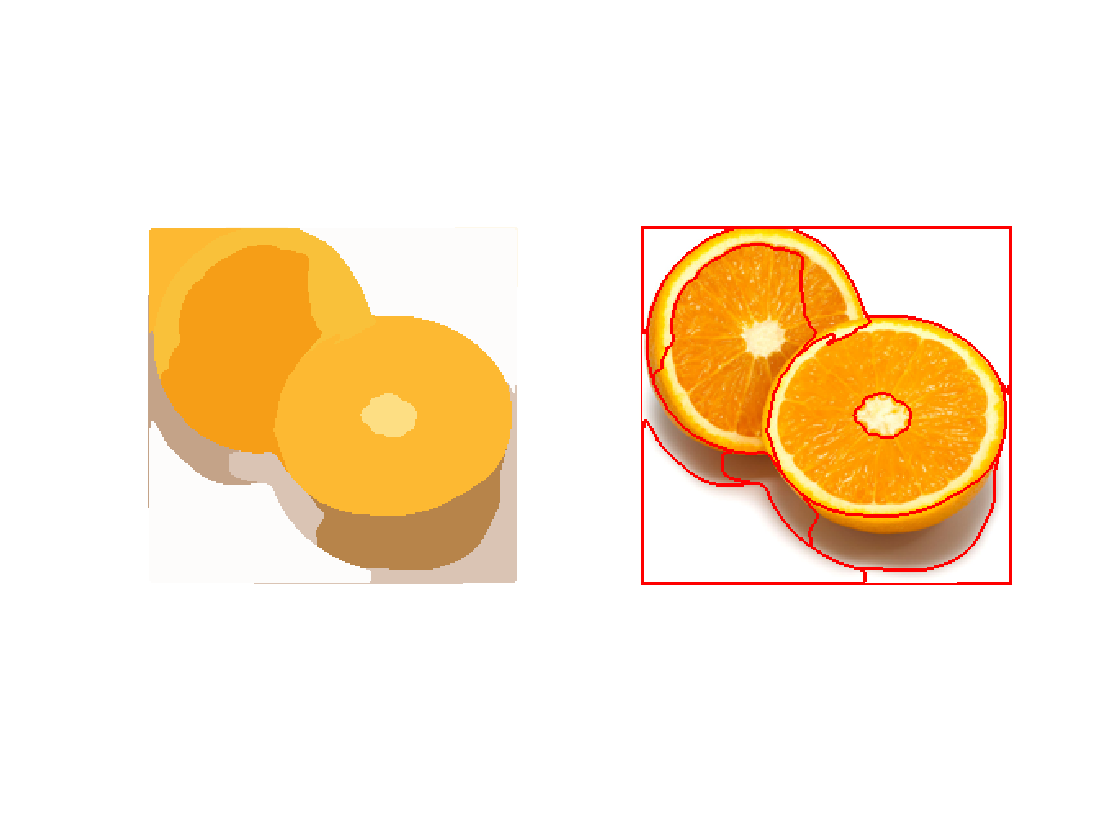

Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/normcuts1.png')
%imwrite(I,'result/normcuts2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(Ibounds);